load('currents_big.mat')
xyz_big = XYZ;
currents_big = currents;

sigma = 3.333E-7; %s/um


electrode_distance = [0,50,0]%um 

electrode_distance =      0    50     0


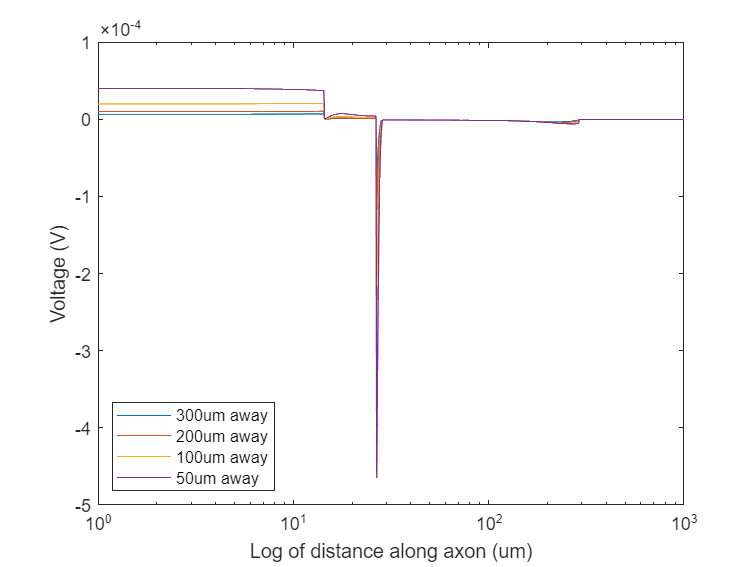


netV50um = sum(calcVext(currents_big, xyz_big, electrode_distance),2);

electrode_distance = [0,100,0];%um 

netV100um = sum(calcVext(currents_big, xyz_big, electrode_distance),2);
electrode_distance = [0,200,0];%um 

netV200um = sum(calcVext(currents_big, xyz_big, electrode_distance),2);
electrode_distance = [0,300,0];%um 

netV300um = sum(calcVext(currents_big, xyz_big, electrode_distance),2);
r = sqrt(( xyz_big(:,1)).^2+(xyz_big(:,2)).^2+(xyz_big(:,3)).^2);

figure
semilogx(sort(r),netV300um)
hold on
semilogx(sort(r),netV200um)
semilogx(sort(r),netV100um)
semilogx(sort(r),netV50um)
legend("300um away", "200um away", "100um away", "50um away", "Location","southwest")
ylabel("Voltage (V)")
xlabel("Log of distance along axon (um)")
xlim([1 10^3])
hold off

load('currents_small.mat')
xyz_small = XYZ;
currents_small = currents;
sigma = 3.333E-7; %s/um
electrode_distance = [0,50,0];%um 

voltageTrace = calcVext(currents_small, xyz_small, electrode_distance);
netV50um = sum(voltageTrace,2);
electrode_distance = [0,100,0];%um 

voltageTrace = calcVext(currents_small, xyz_small, electrode_distance);
netV100um = sum(voltageTrace,2);
electrode_distance = [0,200,0];%um 

voltageTrace = calcVext(currents_small, xyz_small, electrode_distance);
netV200um = sum(voltageTrace,2);
electrode_distance = [0,300,0];%um 

voltageTrace = calcVext(currents_small, xyz_small, electrode_distance);
netV300um = sum(voltageTrace,2);

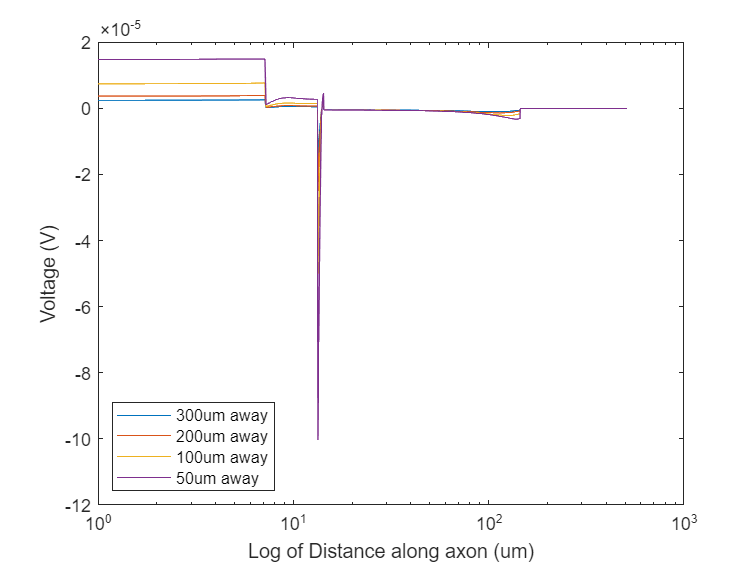

r = sqrt(( xyz_small(:,1)).^2+(xyz_small(:,2)).^2+(xyz_small(:,3)).^2);

figure
semilogx(sort(r),netV300um)
hold on
semilogx(sort(r),netV200um)
semilogx(sort(r),netV100um)
semilogx(sort(r),netV50um)
legend("300um away", "200um away", "100um away", "50um away", "Location","southwest")
hold off
xlabel("Log of Distance along axon (um)")
ylabel("Voltage (V)")

xlim([1 10^3])

# Part 2

load('currents_big.mat')
%currents_big = currents;

sigma = 3.333E-7; %s/um
zeroes = zeros(757, 40000);
locs = [randperm(20,10)', randperm(30,10)', randperm(60,10)']

locs =      6    30    27
    18    14    23
     7    26    45
    16     8    46
    12     3    11
    13    17    60
     3    22    25
     4    20    35
    19    11    37
    20    21    39


sqrt(sum(locs.^2,2))

ans =    40.8044
   32.3883
   52.4404
   49.3559
   16.5529
   63.7024
   33.4365
   40.5093
   43.0232
   48.6004


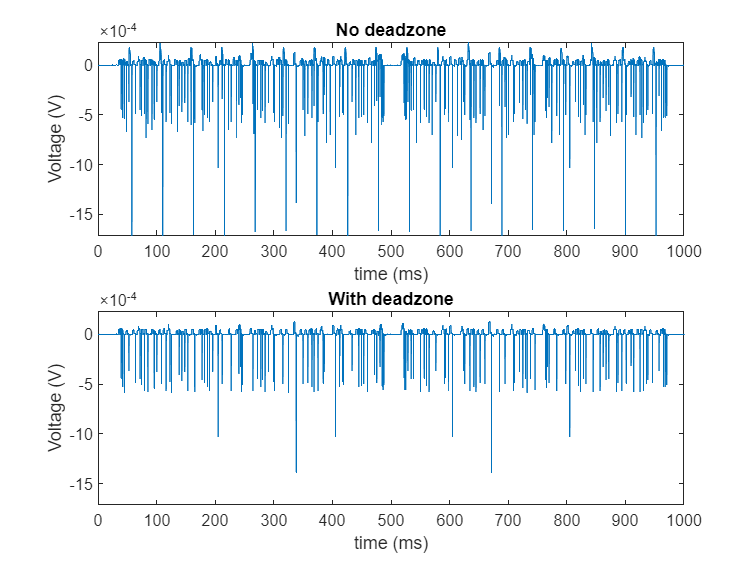


for i = [1:10]
    spikeys = histcounts(linspace(0,1000,10+2*i), 40000);
    spikeys(1,1) = 0;
    spikeys(1,40000) = 0;
    [pattern_, loc] = spikes([spikeys' zeroes'], currents, XYZ, locs(i,:));
    Vext = calcVext(pattern_,loc,[0,0,0]);
    %Vext(isnan(Vext))=0;
    V(i,:) = sum(Vext,2);
    
    [pattern_, loc] = spikes_deadzone([spikeys' zeroes'], currents, XYZ, locs(i,:));
    Vext_dead = calcVext(pattern_,loc,[0,0,0]);
    %Vext_dead(isnan(Vext_dead))=0;
    V_deadzone(i,:) = sum(Vext_dead,2);
end


dt = 0.025;
tTot = 1000;
cn = dsp.ColoredNoise('Color','pink','SamplesPerFrame',tTot/dt);
recordedNoise_unscaled = cn();
recordedNoise = recordedNoise_unscaled/(max(recordedNoise_unscaled)-min(recordedNoise_unscaled))*0.00001;
Vextt = sum(V)+recordedNoise';
Vextt_deadzone = sum(V_deadzone)+recordedNoise';

subplot(2,1,1)
t = [0:dt:(1000-dt)];
plot(t,Vextt)
title("No deadzone")
xlabel("time (ms)")
ylabel("Voltage (V)")
ylim([min(Vextt), max(Vextt)])
subplot(2,1,2)
plot(t,Vextt_deadzone)
xlabel("time (ms)")
ylabel("Voltage (V)")
ylim([min(Vextt), max(Vextt)])
title("With deadzone")
hold off

dataset = load("517lab3IH_dataPart2.txt");
k_XYZ = dataset(:,1:3)*1000;
k_V = dataset(:,4)*0.001;

cellXYZ = XYZ;
cellXYZ(:,3) = cellXYZ(:,3)+50;
d = [min(cellXYZ(:,1)):0.25:max(cellXYZ(:,1))]

d =  -514.3750 -514.1250 -513.8750 -513.6250 -513.3750 -513.1250 -512.8750 -512.6250 -512.3750 -512.1250 -511.8750 -511.6250 -511.3750 -511.1250 -510.8750 -510.6250 -510.3750 -510.1250 -509.8750 -509.6250 -509.3750 -509.1250 -508.8750 -508.6250 -508.3750 -508.1250 -507.8750 -507.6250 -507.3750 -507.1250 -506.8750 -506.6250 -506.3750 -506.1250 -505.8750 -505.6250 -505.3750 -505.1250 -504.8750 -504.6250 -504.3750 -504.1250 -503.8750 -503.6250 -503.3750 -503.1250 -502.8750 -502.6250 -502.3750 -502.1250


[xq,yq, zq] = meshgrid(d, 0, 50);
Vinter = griddata(k_XYZ(:,1), k_XYZ(:,2), k_XYZ(:,3), k_V, cellXYZ(:,1), cellXYZ(:,2), cellXYZ(:,3));
F = fillmissing(Vinter,'linear');
V_ext = sum(F.*currents,2)

V_ext = 	1.0e+-9 *

    0.0322
    0.0322
    0.0322
    0.0322
    0.0323
    0.0323
    0.0323
    0.0323
    0.0323
    0.0323


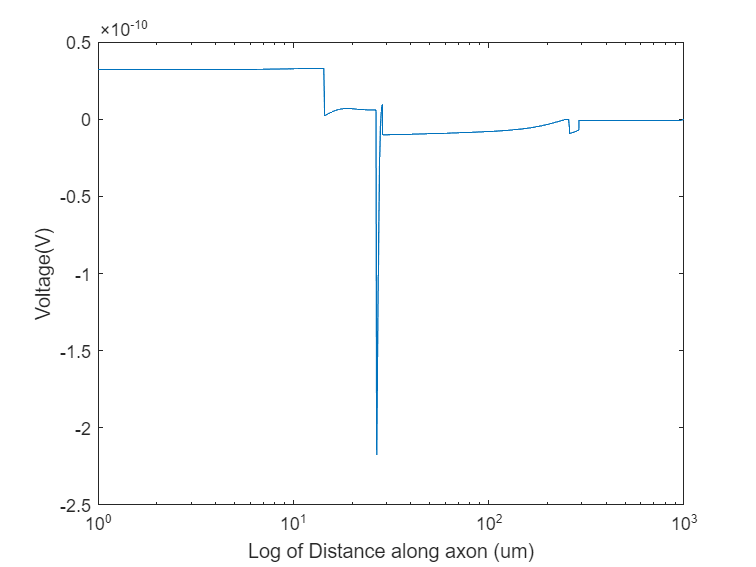

r = sqrt(( xyz_big(:,1)).^2+(xyz_big(:,2)).^2+(xyz_big(:,3)).^2);
figure()
semilogx(sort(r),V_ext)
ylabel('Voltage(V)')
xlabel("Log of Distance along axon (um)")
xlim([1 10^3])

# Part 4

%threshold = 32
dt = 0.1

dt = 0.1000

sigma = 3.333E-7; 
l = [-2.5:dt:2.5]*0.001; %m
d = 1*0.001; %m
I = 0.0225; %mA
r = sqrt(l.^2+d^2);
Voltage = I./(4.*pi.*r.*sigma)

Voltage = 	1.0e+06 *

    1.9951    2.0662    2.1420    2.2230    2.3096    2.4024    2.5020    2.6089    2.7237    2.8472    2.9799    3.1224    3.2754    3.4391    3.6136    3.7986    3.9930    4.1948    4.4009    4.6065    4.8049    4.9878    5.1455    5.2677    5.3454    5.3720    5.3454    5.2677    5.1455    4.9878    4.8049    4.6065    4.4009    4.1948    3.9930    3.7986    3.6136    3.4391    3.2754    3.1224    2.9799    2.8472    2.7237    2.6089    2.5020    2.4024    2.3096    2.2230    2.1420    2.0662


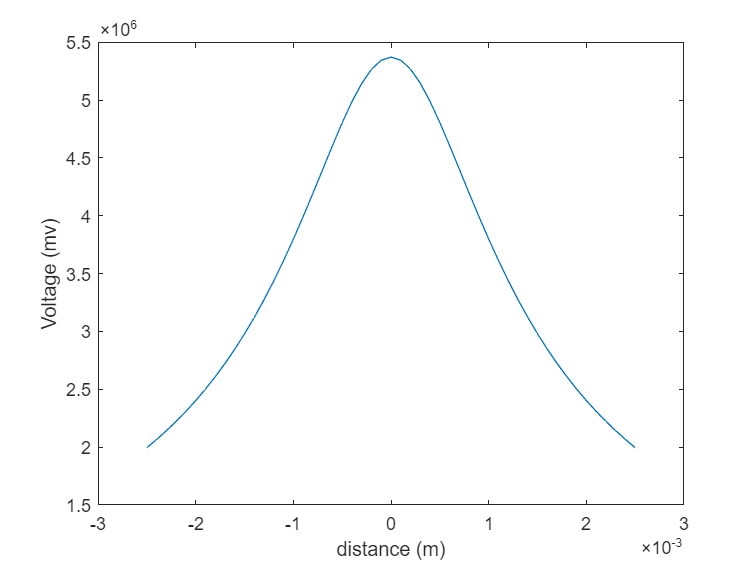

figure()
plot(l,Voltage)
xlabel('distance (m)')
ylabel('Voltage (mv)')

ga = 3E-5

ga = 3.0000e-05

dVd2 = diff(diff(Voltage))./dt^2;
I = ga*dVd2;
stim= max(I)

stim = 32.4699

%I = 0.0225mA needed for stimulus